# ISC quantification - tmem16a 

% - event freq (# of waves/min)
maxTime = 10.11614  % 1250 frames

maxTime = 10.1161

scale = 0.83027; %um/pixel
areaPG = (10*scale)^2 % area per grd

areaPG = 68.9348


con1 = load('20201113 exp389 mouse 1 tectacre tmem16fl+ gc3 1x movie 4_ISCdata.mat'); 
con2 = load('20201022 exp380 tecta cre tmem16fl+ gcamp3 mouse 1 prep 1 10 min_ISCdata.mat'); 
con3 = load('20201022 exp380 tecta cre tmem16fl+ gcamp3 mouse 2 prep 1 10 min_ISCdata.mat');
con4 = load('20210414 exp425 mouse 3 prep1 tec ta cre tmem16fl+ gc3 movie 1x_ISCdata.mat');
con5 = load('20210414 exp425 mouse 3 prep2 tecta cre tmem16fl+ gc3 movie 1x_ISCdata.mat');
con6 = load('20201216 exp396 mouse8 prep 2 tecta tmem16a fl+ gc3 1x movie 3_ISCdata.mat'); % no IHC data for this prep

con1Freq = (length(con1.ISCstruct.event)/maxTime);
con2Freq = (length(con2.ISCstruct.event)/maxTime);
con3Freq = (length(con3.ISCstruct.event)/maxTime);
con4Freq = (length(con4.ISCstruct.event)/maxTime);
con5Freq = (length(con5.ISCstruct.event)/maxTime);
con6Freq = (length(con6.ISCstruct.event)/maxTime);

conFreq = [con1Freq,con2Freq,con3Freq,con4Freq,con5Freq,con6Freq]

conFreq =    18.2876   16.5083   16.6071   12.8508   14.1358   11.9611



cko1 = load('20201124 exp392 mouse 8 prep 1 tecta cre tmem16a gc3 1x_ISCdata.mat');
cko2 = load('20201124 exp392 mouse 8 prep 2 tecta cre tmem16a gc3 movie 4 1x_ISCdata.mat');
cko3 = load('20210106 exp400 mouse 8 prep 1 tecta cre tmem16flfl gc3 movie 2_ISCdata.mat');
cko4 = load('20210106 exp400 mouse 10 prep 1 tecta cre tmem16flfl gc3 movie 1_ISCdata.mat');
cko5 = load('20210106 exp400 mouse 10 prep 2 tecta cre tmem16flfl gc3 movie 1_ISCdata.mat');
cko6 = load('20210106 exp400 mouse 12 prep 1 tecta cre tmem16flfl gc3 movie 1_ISCdata.mat'); 

cko1Freq = (length(cko1.ISCstruct.event)/maxTime);
cko2Freq = (length(cko2.ISCstruct.event)/maxTime);
cko3Freq = (length(cko3.ISCstruct.event)/maxTime);
cko4Freq = (length(cko4.ISCstruct.event)/maxTime);
cko5Freq = (length(cko5.ISCstruct.event)/maxTime);
cko6Freq = (length(cko6.ISCstruct.event)/maxTime);

ckoFreq = [cko1Freq,cko2Freq,cko3Freq,cko4Freq,cko5Freq,cko6Freq]

ckoFreq =    18.5842   13.3450   13.2462   15.4209   17.1014   12.0599



conditions = {'Control','cKO'};
markSz = [20 20]

markSz =     20    20


dim = [1 2];
ylbl = ('Events per minute');
[fig1 h p1] = compare2(conFreq,ckoFreq,conditions,ylbl,dim,markSz)

not normal


fig1 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   0


p1 = 0.9372

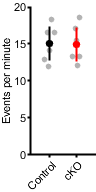

ylim([0 20]);


% mean amplitude
con1Amp = (mean([con1.ISCstruct.event.maxAmplitude]));
con2Amp = (mean([con2.ISCstruct.event.maxAmplitude]));
con3Amp = (mean([con3.ISCstruct.event.maxAmplitude]));
con4Amp = (mean([con4.ISCstruct.event.maxAmplitude]));
con5Amp = (mean([con5.ISCstruct.event.maxAmplitude]));
con6Amp = (mean([con6.ISCstruct.event.maxAmplitude]));

conAmp = [con1Amp,con2Amp,con3Amp,con4Amp,con5Amp,con6Amp]*100;

cko1Amp = (mean([cko1.ISCstruct.event.maxAmplitude]));
cko2Amp = (mean([cko2.ISCstruct.event.maxAmplitude]));
cko3Amp = (mean([cko3.ISCstruct.event.maxAmplitude]));
cko4Amp = (mean([cko4.ISCstruct.event.maxAmplitude]));
cko5Amp = (mean([cko5.ISCstruct.event.maxAmplitude]));
cko6Amp = (mean([cko6.ISCstruct.event.maxAmplitude]));

ckoAmp = [cko1Amp,cko2Amp,cko3Amp,cko4Amp,cko5Amp,cko6Amp]*100;
conditions = {'Control','cKO'};
markSz = [20 20]

markSz =     20    20


dim = [1 2];
ylbl = ('Mean amplitude (%df/f)');
[fig2 h p2] = compare2(conAmp,ckoAmp,conditions,ylbl,dim,markSz)

not normal


fig2 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   0


p2 = 0.3095

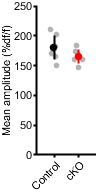

ylim([0 250]);


%mean duration
secPerFrame = 0.4855

secPerFrame = 0.4855

con1Dur = mean([con1.ISCstruct.event.eventDuration])*secPerFrame;
con2Dur = mean([con2.ISCstruct.event.eventDuration])*secPerFrame;
con3Dur = mean([con3.ISCstruct.event.eventDuration])*secPerFrame;
con4Dur = mean([con4.ISCstruct.event.eventDuration])*secPerFrame;
con5Dur = mean([con5.ISCstruct.event.eventDuration])*secPerFrame;
con6Dur = mean([con6.ISCstruct.event.eventDuration])*secPerFrame;

cko1Dur = mean([cko1.ISCstruct.event.eventDuration]*secPerFrame);
cko2Dur = mean([cko2.ISCstruct.event.eventDuration]*secPerFrame);
cko3Dur = mean([cko3.ISCstruct.event.eventDuration]*secPerFrame);
cko4Dur = mean([cko4.ISCstruct.event.eventDuration]*secPerFrame);
cko5Dur = mean([cko5.ISCstruct.event.eventDuration]*secPerFrame);
cko6Dur = mean([cko6.ISCstruct.event.eventDuration]*secPerFrame);

conDur = [con1Dur,con2Dur,con3Dur,con4Dur,con5Dur,con6Dur]

conDur =     3.4851    3.5613    3.7453    3.6562    3.1507    4.5541


ckoDur = [cko1Dur,cko2Dur,cko3Dur,cko4Dur,cko5Dur,cko6Dur]

ckoDur =     2.8975    3.5747    3.2681    3.2149    2.8793    3.2712



ylbl = ('Mean duration (s)');
[fig3 h p3] = compare2(conDur,ckoDur,conditions,ylbl,dim,markSz)

not normal


fig3 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   0


p3 = 0.0649

p3

p3 = 0.0649

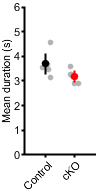

ylim([0 6])

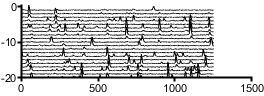

% Rasters
[x,n] = size(con6.ISCstruct.rois);
t = 1250;
numToShow = 20;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(con6.ISCstruct.rois(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[2.75 1])

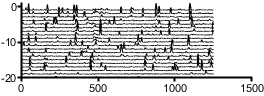


[x,n] = size(cko4.ISCstruct.rois);
t = 1250;
numToShow = 20;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(cko4.ISCstruct.rois(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[2.75 1])

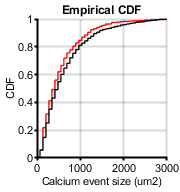


% event size

conSize = [[con1.ISCstruct.event.area],[con2.ISCstruct.event.area],[con3.ISCstruct.event.area],[con4.ISCstruct.event.area],[con5.ISCstruct.event.area],[con6.ISCstruct.event.area]]*areaPG;
ckoSize = [[cko1.ISCstruct.event.area],[cko2.ISCstruct.event.area],[cko3.ISCstruct.event.area],[cko4.ISCstruct.event.area],[cko5.ISCstruct.event.area],[cko6.ISCstruct.event.area]]*areaPG;


% CDF
figure
h1 = cdfplot(ckoSize);
hold on
h2 = cdfplot(conSize);
h1.Color = 'r';
h2.Color = 'k';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Calcium event size (um2)');
ylabel('CDF');
xlim([0 3000])
xticks([0 1000 2000 3000])
figQuality(gcf,gca,[1.87 2])


[h p] = kstest2(conSize,ckoSize);
p

p = 0.0131

% how many events? 
length(conSize)

ans = 914

length(ckoSize)

ans = 908


% mean event size

conMeanSize = [mean([con1.ISCstruct.event.area]),mean([con2.ISCstruct.event.area]),mean([con3.ISCstruct.event.area]),mean([con4.ISCstruct.event.area]),mean([con5.ISCstruct.event.area]),mean([con6.ISCstruct.event.area])]*areaPG;
ckoMeanSize = [mean([cko1.ISCstruct.event.area]),mean([cko2.ISCstruct.event.area]),mean([cko3.ISCstruct.event.area]),mean([cko4.ISCstruct.event.area]),mean([cko5.ISCstruct.event.area]),mean([cko6.ISCstruct.event.area])]*areaPG;

conditions = {'Control','cKO'};
markSz = [20 20]

markSz =     20    20


dim = [1 2];
ylbl = ('Mean event size (um2)');
[fig4 h p4] = compare2(conMeanSize,ckoMeanSize,conditions,ylbl,dim,markSz)

not normal


fig4 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 67
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   1


p4 = 0.0260

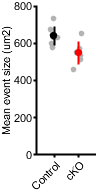

ylim([0 800]);


subP = handleTheSubplot({fig1,fig2,fig3,fig4},[1 4]);

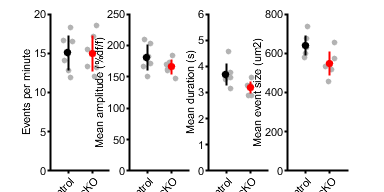

figQuality(subP,gca,[4 2])


[CorrP CorrA h] = fdr_BH([p1,p2,p3,p4],0.05)

CorrP =     0.9372    0.4127    0.1299    0.1039


CorrA =     0.0500    0.0375    0.0250    0.0125


h = 4×1 logical array
   0
   0
   0
   0



% correlation analysis with hair cells

% get normalized ISC trace for all cells

con1Trace = (sum([con1.ISCstruct.rois],2));
con1TraceNorm = con1Trace/max(con1Trace);

con1IHC = load('20201113 exp389 mouse 1 tectacre tmem16fl+ gc3 1x movie 4_IHCstruct.mat');

con1ISCIHC = corr(con1TraceNorm,con1IHC.IHCstruct.roisignalNorm(:,:));
meancon1Cor = prctile(con1ISCIHC,80,'all')

meancon1Cor = single
0.4605


con2Trace = (sum([con2.ISCstruct.rois],2));
con2TraceNorm = con2Trace/max(con2Trace);

con2IHC = load('20201022 exp380 tecta cre tmem16fl+ gcamp3 mouse 1 prep 1 10 min_IHCstruct.mat');

con2ISCIHC = corr(con2TraceNorm,con2IHC.IHCstruct.roisignalNorm(:,:));
meancon2Cor = prctile(con2ISCIHC,80,'all') 

meancon2Cor = single
0.4744


con3Trace = (sum([con3.ISCstruct.rois],2));
con3TraceNorm = con3Trace/max(con3Trace);

con3IHC = load('20201022 exp380 tecta cre tmem16fl+ gcamp3 mouse 2 prep 1 10 min_IHCstruct.mat');

con3ISCIHC = corr(con3TraceNorm,con3IHC.IHCstruct.roisignalNorm(:,:));
meancon3Cor = prctile(con3ISCIHC,80,'all')

meancon3Cor = single
0.4198


con4Trace = (sum([con4.ISCstruct.rois],2));
con4TraceNorm = con4Trace/max(con4Trace);

con4IHC = load('20210414 exp425 mouse 3 prep1 tec ta cre tmem16fl+ gc3 movie 1x_IHCstruct.mat');

con4ISCIHC = corr(con4TraceNorm,con4IHC.IHCstruct.roisignalNorm(:,:));
meancon4Cor = prctile(con4ISCIHC,80,'all')

meancon4Cor = single
0.4295


con5Trace = (sum([con5.ISCstruct.rois],2));
con5TraceNorm = con5Trace/max(con5Trace);

con5IHC = load('20210414 exp425 mouse 3 prep2 tecta cre tmem16fl+ gc3 movie 1x_IHCstruct.mat');

con5ISCIHC = corr(con5TraceNorm,con5IHC.IHCstruct.roisignalNorm(:,:));
meancon5Cor = prctile(con5ISCIHC,80,'all')

meancon5Cor = single
0.3788


meanConCor = [meancon1Cor,meancon2Cor,meancon3Cor,meancon4Cor,meancon5Cor];


% cKO
cko1Trace = (sum([cko1.ISCstruct.rois],2));
cko1TraceNorm = cko1Trace/max(cko1Trace);

cko1IHC = load('20201124 exp392 mouse 8 prep 1 tecta cre tmem16a gc3 1x_IHCstruct.mat');

cko1ISCIHC = corr(cko1TraceNorm,cko1IHC.IHCstruct.roisignalNorm(:,:));
meancko1Cor = prctile(cko1ISCIHC,80,'all') 

meancko1Cor = single
0.2979


cko2Trace = (sum([cko2.ISCstruct.rois],2));
cko2TraceNorm = cko2Trace/max(cko2Trace);

cko2IHC = load('20201124 exp392 mouse 8 prep 2 tecta cre tmem16a gc3 movie 4 1x_IHCstruct.mat');

cko2ISCIHC = corr(cko2TraceNorm,cko2IHC.IHCstruct.roisignalNorm(:,:));
meancko2Cor = prctile(cko2ISCIHC,80,'all') 

meancko2Cor = single
0.2613


cko3Trace = (sum([cko3.ISCstruct.rois],2));
cko3TraceNorm = cko3Trace/max(cko3Trace);

cko3IHC = load('20210106 exp400 mouse 8 prep 1 tecta cre tmem16flfl gc3 movie 2_IHCstruct.mat');

cko3ISCIHC = corr(cko3TraceNorm,cko3IHC.IHCstruct.roisignalNorm(:,:));
meancko3Cor = prctile(cko3ISCIHC,80,'all') 

meancko3Cor = single
0.2218


cko4Trace = (sum([cko4.ISCstruct.rois],2));
cko4TraceNorm = cko4Trace/max(cko4Trace);

cko4IHC = load('20210106 exp400 mouse 10 prep 1 tecta cre tmem16flfl gc3 movie 1_IHCstruct.mat');

cko4ISCIHC = corr(cko4TraceNorm,cko4IHC.IHCstruct.roisignalNorm(:,:));
meancko4Cor = prctile(cko4ISCIHC,80,'all') 

meancko4Cor = single
0.1917


cko5Trace = (sum([cko5.ISCstruct.rois],2));
cko5TraceNorm = cko5Trace/max(cko5Trace);

cko5IHC = load('20210106 exp400 mouse 10 prep 2 tecta cre tmem16flfl gc3 movie 1_IHCstruct.mat');

cko5ISCIHC = corr(cko5TraceNorm,cko5IHC.IHCstruct.roisignalNorm(:,:));
meancko5Cor = prctile(cko5ISCIHC,80,'all') 

meancko5Cor = single
0.1425


cko6Trace = (sum([cko6.ISCstruct.rois],2));
cko6TraceNorm = cko6Trace/max(cko6Trace);

cko6IHC = load('20210106 exp400 mouse 12 prep 1 tecta cre tmem16flfl gc3 movie 1_IHCstruct.mat');

cko6ISCIHC = corr(cko6TraceNorm,cko6IHC.IHCstruct.roisignalNorm(:,:));
meancko6Cor = prctile(cko6ISCIHC,80,'all') 

meancko6Cor = single
0.1961


meanckoCor = [meancko1Cor,meancko2Cor,meancko3Cor,meancko4Cor,meancko5Cor,meancko6Cor];

conditions = {'Control','cKO'};
markSz = [20 20]

markSz =     20    20


dim = [1 2];
ylbl = ('Mean ISC-IHC correlation');
[fig5 h p5] = compare2(meanConCor,meanckoCor,conditions,ylbl,dim,markSz)

not normal


fig5 =   Figure (LiveEditorRunTimeFigure) with properties:

      Number: 5
        Name: ''
       Color: [1 1 1]
    Position: [0 0 1 2]
       Units: 'inches'

  Show all properties


h = logical
   1


p5 = 0.0043

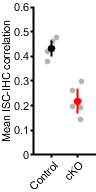

ylim([0 0.6]);

subP = handleTheSubplot({fig5,fig5,fig5},[1 3]);

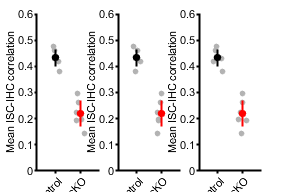

figQuality(subP,gca,[3 2])

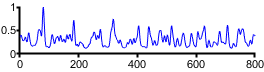

% plot example for figure

% Rasters
figure; plot(con2TraceNorm(1:800),'Color','b')
figQuality(gcf,gca,[2.75 0.75])
ylim([0 1])

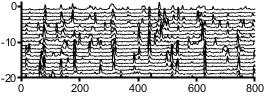


[x,n] = size(con2IHC.IHCstruct.roisignalNorm);
t = 800;
numToShow = 20;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(con2IHC.IHCstruct.roisignalNorm(1:800,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[2.75 1])

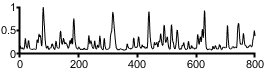


con2IHCTrace = (sum([con2IHC.IHCstruct.roisignalNorm],2));
con2IHCTraceNorm = con2IHCTrace/max(con2IHCTrace);

figure; plot(con2IHCTrace(1:800),'Color','k')
figQuality(gcf,gca,[2.75 0.75])
ylim([0 80])

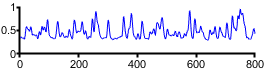



figure; plot(cko6TraceNorm(1:800),'Color','b')
figQuality(gcf,gca,[2.75 0.75])
ylim([0 1])

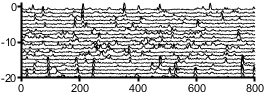


[x,n] = size(cko6IHC.IHCstruct.roisignalNorm);
t = 800;
numToShow = 20;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(cko6IHC.IHCstruct.roisignalNorm(1:800,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[2.75 1])

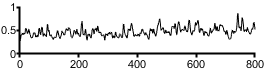


cko6IHCTrace = (sum([cko6IHC.IHCstruct.roisignalNorm],2));
cko6IHCTraceNorm = cko6IHCTrace/max(cko6IHCTrace);
figure; plot(cko6IHCTrace(1:800),'Color','k')
figQuality(gcf,gca,[2.75 0.75])
ylim([0 80])